Reference: [https://www.mathworks.com/matlabcentral/fileexchange/68576-stock-prediction-using-arima](https://www.mathworks.com/matlabcentral/fileexchange/68576-stock-prediction-using-arima)

% from: https://finance.yahoo.com/quote/5099.KL/history/
% Capital A Berhad, operating as AirAsia, is a Malaysian multinational low-cost airline
warning('OFF', 'MATLAB:table:ModifiedAndSavedVarnames');
StockData = readtable('5099.KL.csv','ReadVariableNames',true); 

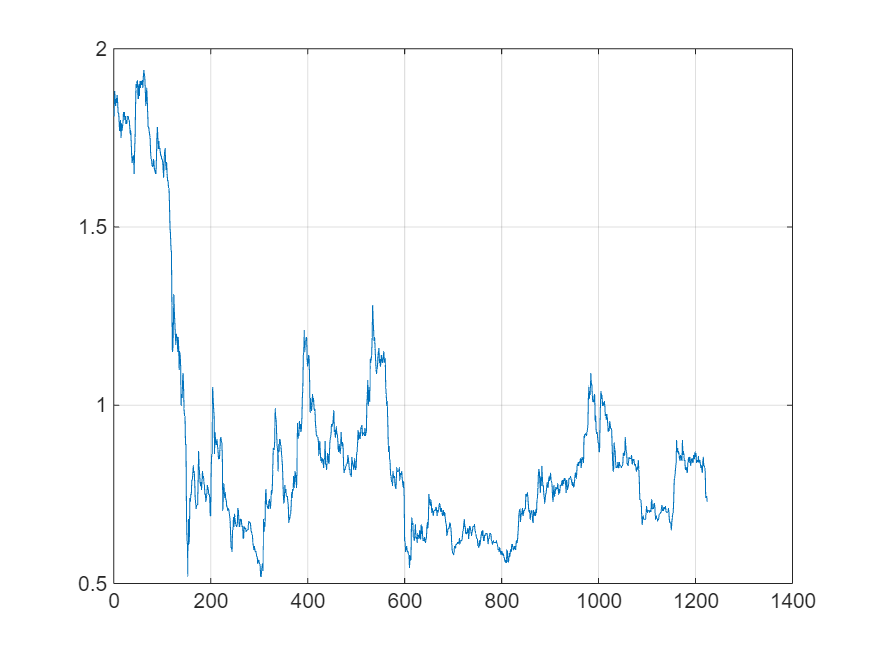

figure("Name",'Original Data')
plot(StockData.Close)
grid on

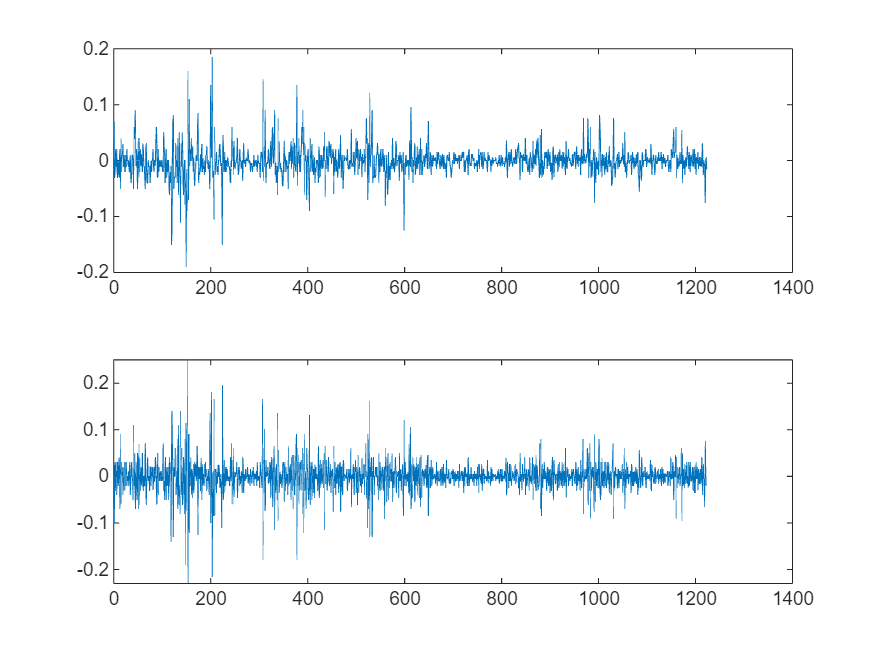

figure("Name",'Diff = Detrend')
subplot(211)
plot(diff(StockData.Close))
subplot(212)
plot(diff(diff(StockData.Close)))

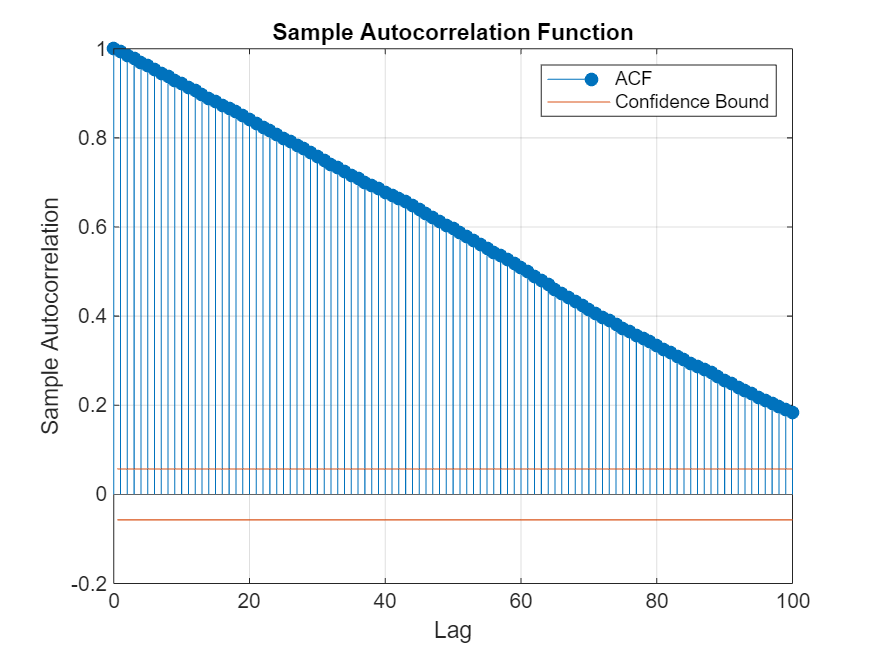

figure
autocorr(StockData.Close,"NumLags",100)

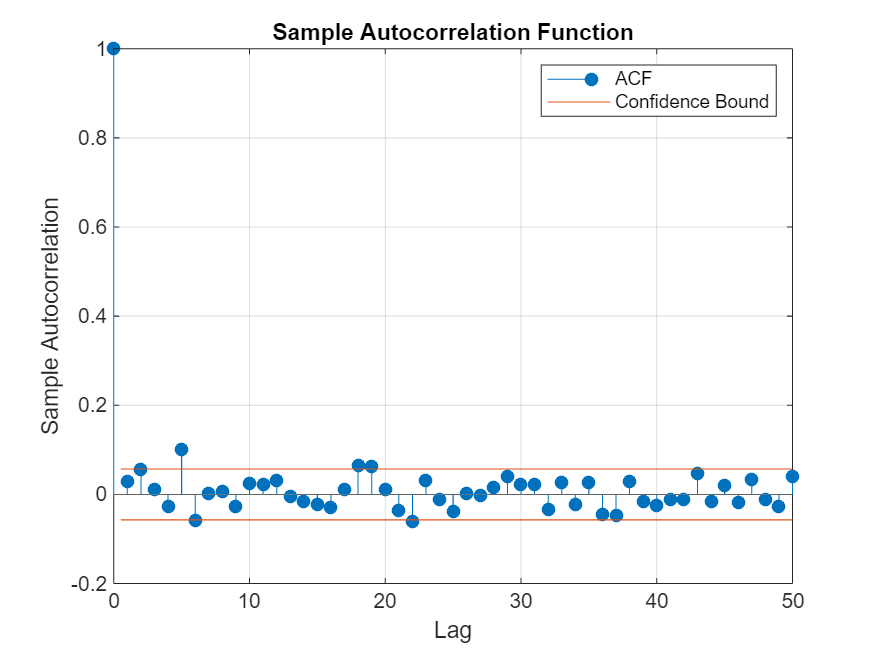

figure
autocorr(diff(StockData.Close),'NumLags',50)

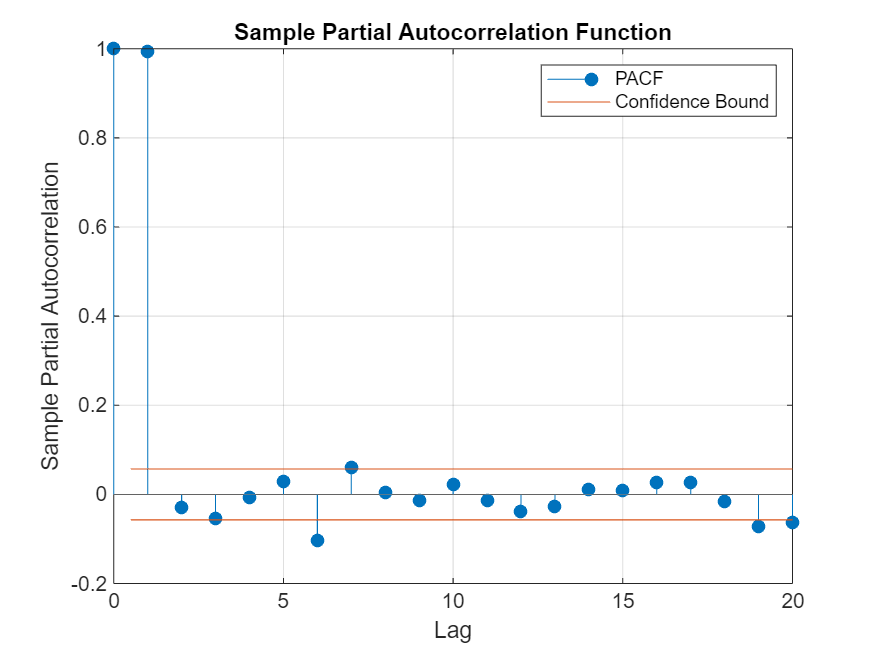

figure
parcorr(StockData.Close)

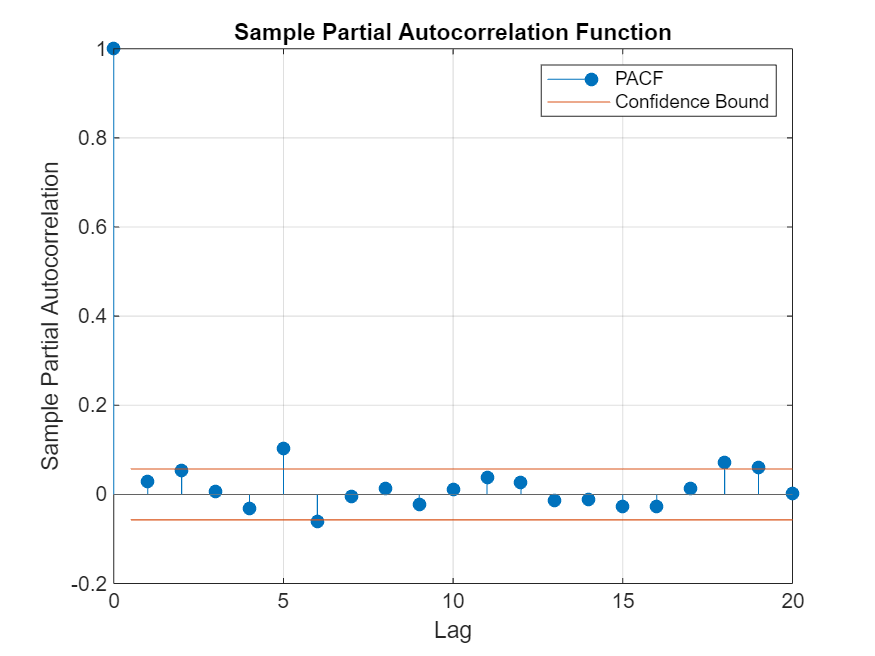

figure
parcorr(diff(StockData.Close))

p = 3;
q = 3;
d = 1;
Mdl = arima(p,d,q);
[Mdl,~,logL] = estimate(Mdl,StockData.Close);

 
    ARIMA(3,1,3) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant    -0.0045838      0.0034465         -1.33         0.18352
    AR{1}          -1.6137        0.17181       -9.3925      5.8614e-21
    AR{2}          -1.1772        0.26333       -4.4703      7.8117e-06
    AR{3}         -0.30682        0.16522       -1.8571        0.063301
    MA{1}           1.6468        0.16936        9.7236      2.3928e-22
    MA{2}           1.2781         0.2523         5.066       4.062e-07
    MA{3}           0.4117        0.15844        2.5985       0.0093632
    Variance     0.0007322 

[~,~,ic] = aicbic(logL,p+q+d,length(StockData.Close))

ic = struct with fields:
     aic: -5.3490e+03
     bic: -5.3133e+03
    aicc: -5.3490e+03
    caic: -5.3063e+03
     hqc: -5.3356e+03


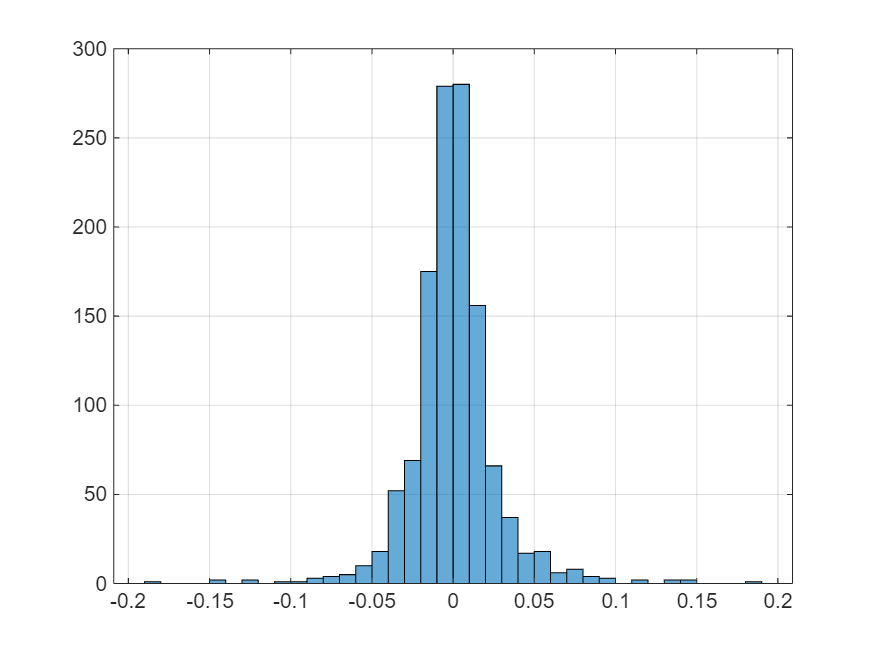

residual = infer(Mdl,StockData.Close);
histogram(residual)
grid on

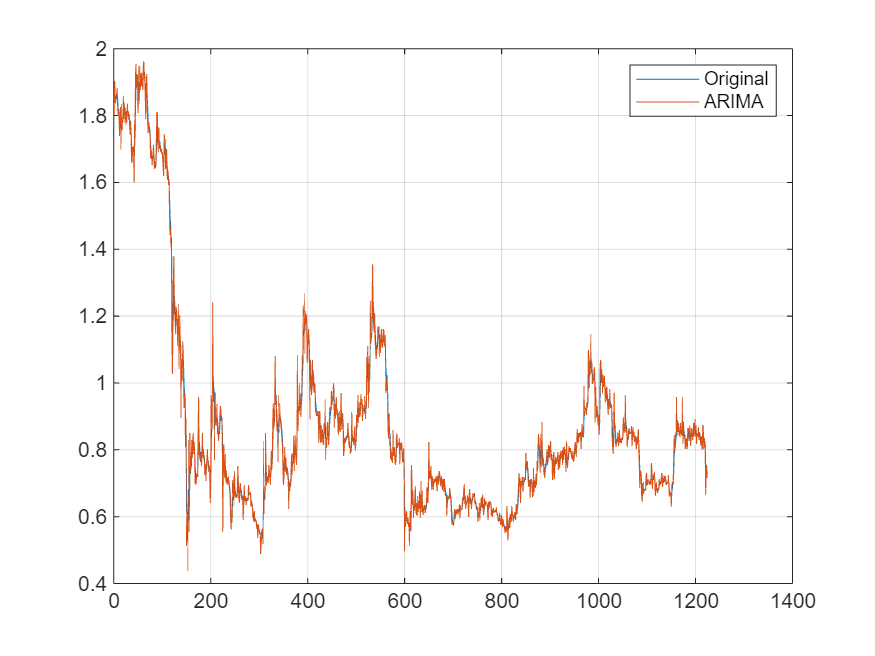

figure
plot(StockData.Close)
hold on
plot(StockData.Close + residual)
hold off
legend('Original','ARIMA')
grid on

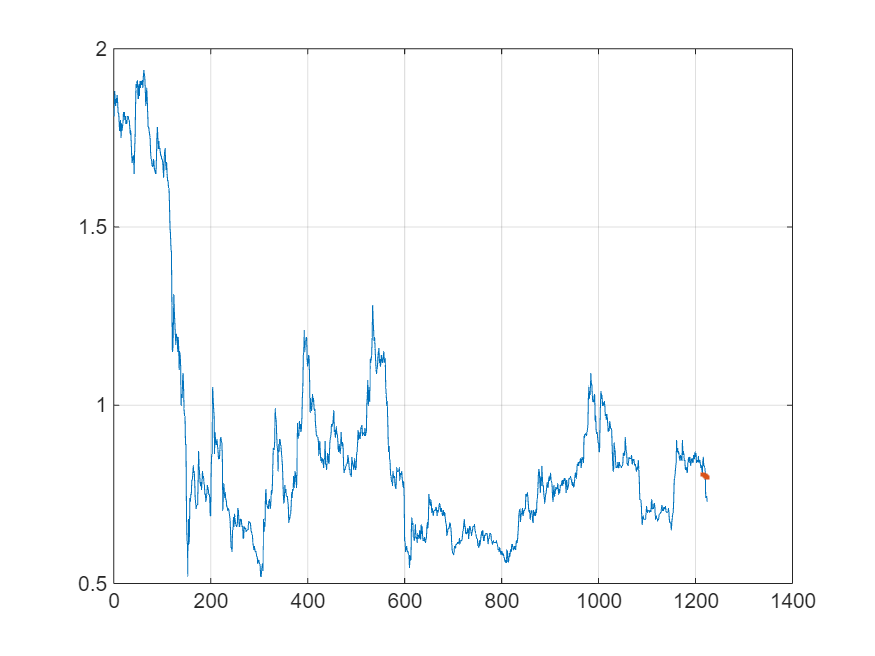

fr = forecast(Mdl,10,'Y0',StockData.Close(1:end-10));
figure
plot(StockData.Close)
hold on
ln = length(StockData.Close);
plot(ln-9:ln,fr,'.-')
grid on